clc;
clear;

% Define the number of observations of X
N = 100;
x = randn(N, 4);

% Separate the columns of x
x1 = x(:,1);
x2 = x(:,2);
x3 = x(:,3);
x4 = x(:,4);

% Define new variables based on the columns of x
x5 = 0.4 * x1 + 0.7 * x2 - 1.8 * x4;
x6 = 0.8 * x1 + 1.2 * x3 + x4;

% Combine the variables into a matrix X
X = [x1, x2, x3, x4, x5, x6];

% Perform SVD on noise-free variables
[U, S, V] = svd(X, 'econ');

% Identify right singular vectors corresponding to zero singular values
null_space = V(:,5:end);
v_1 = null_space(:,1);
v_2 = null_space(:,2);

% Calculate the dot product
dot_product = dot(v_1, v_2);

% Calculate the cosine of the angle
mag_v_1 = norm(v_1);
mag_v_2 = norm(v_2);
cosine_angle = dot_product / (mag_v_1 * mag_v_2);

% Calculate the angle in radians
angle_radians = acos(cosine_angle);

% Convert the angle to degrees
angle_degrees = rad2deg(angle_radians)

angle_degrees = 90.0000


% Define the matrix A
A = [0.4 0.7 0 -1.8 -1 0; 0.8 0 1.2 1 0 -1]

A =     0.4000    0.7000         0   -1.8000   -1.0000         0
    0.8000         0    1.2000    1.0000         0   -1.0000



% Fetch the constraints
C =  V \ A.'

C =    -0.0000   -0.0000
    0.0000    0.0000
   -0.0000    0.0000
    0.0000    0.0000
   -1.1852   -1.2502
   -1.8669    1.5865



% Calculate x_hat to prove x=A
x_hat = round((v_1 * C(5,:) + v_2 * C(6,:)) .* 10) ./ 10

x_hat =     0.4000    0.8000
    0.7000         0
         0    1.2000
   -1.8000    1.0000
   -1.0000         0
         0   -1.0000


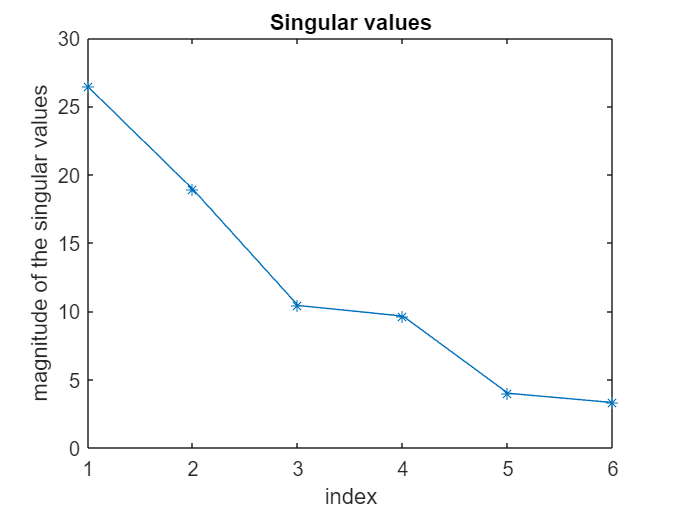


% Define the SNR
SNR = 10;

% Generate noise
noise_std = sqrt(var(X) / SNR);
noise_std = diag(noise_std);
ek = randn(N, 6) * noise_std;

% Add noise to the data
Z = [x1, x2, x3, x4, x5, x6] + ek;

% Perform SVD on noisy variables
[UU, SS, VV] = svd(Z, 'econ');
S_diag = diag(SS);

% Plot the singular values
p = plot(S_diag);
p.Marker = '*';
title('Singular values');
xlabel('index');
ylabel('magnitude of the singular values');


% Reconstruct Z_hat with rank four approximation
Zhat_4 = UU(:,1:4) * SS(1:4,1:4) * VV(:,1:4)';
n_4 = norm(Z - Zhat_4, 2); % Induced 2-norm of the matrix

% Reconstruct Z_hat with rank five approximation
Zhat_5 = UU(:,1:5) * SS(1:5,1:5) * VV(:,1:5)';
n_5 = norm(Z - Zhat_5, 2); % Induced 2-norm of the matrix
for i = [1 2 4 5 6]
    disp((dot(V(:,3).',V(:,i))));
end

  -1.0408e-16

  -2.0817e-16

  -1.0235e-16

  -7.6328e-17

  -3.5388e-16



V

V =    -0.0704    0.2628   -0.2163   -0.7829   -0.5050    0.1063
   -0.2195    0.0723    0.9109   -0.0659   -0.2635   -0.2077
   -0.0213    0.5069   -0.0800    0.5829   -0.5316    0.3375
    0.3718   -0.0272    0.3328   -0.1751    0.2346    0.8152
   -0.8510    0.2047   -0.0479   -0.0441    0.3764    0.2967
    0.2899    0.7913    0.0637   -0.1020    0.4430   -0.2812


V1 = cat(1,A,V)

V1 =     0.4000    0.7000         0   -1.8000   -1.0000         0
    0.8000         0    1.2000    1.0000         0   -1.0000
   -0.0704    0.2628   -0.2163   -0.7829   -0.5050    0.1063
   -0.2195    0.0723    0.9109   -0.0659   -0.2635   -0.2077
   -0.0213    0.5069   -0.0800    0.5829   -0.5316    0.3375
    0.3718   -0.0272    0.3328   -0.1751    0.2346    0.8152
   -0.8510    0.2047   -0.0479   -0.0441    0.3764    0.2967
    0.2899    0.7913    0.0637   -0.1020    0.4430   -0.2812


rank(V1)

ans = 6